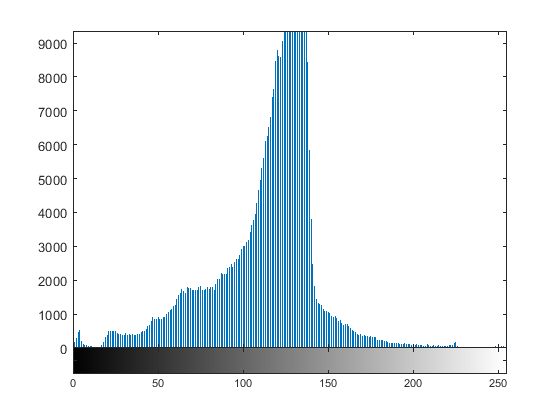

I = imread("Goal.jpg");
G = rgb2gray(I);
imhist (G);

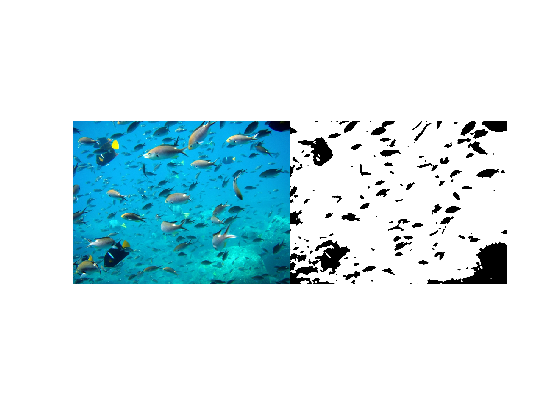

bw = G>90;
se = strel('disk',2);
Iopenned = imopen(bw,se);
Iclosed = imclose(Iopenned,se);
imshowpair (I,Iclosed,'montage')
[L,n]=bwlabel(~Iclosed,4);
r=regionprops(L,'BoundingBox');
figure, imshow(I);

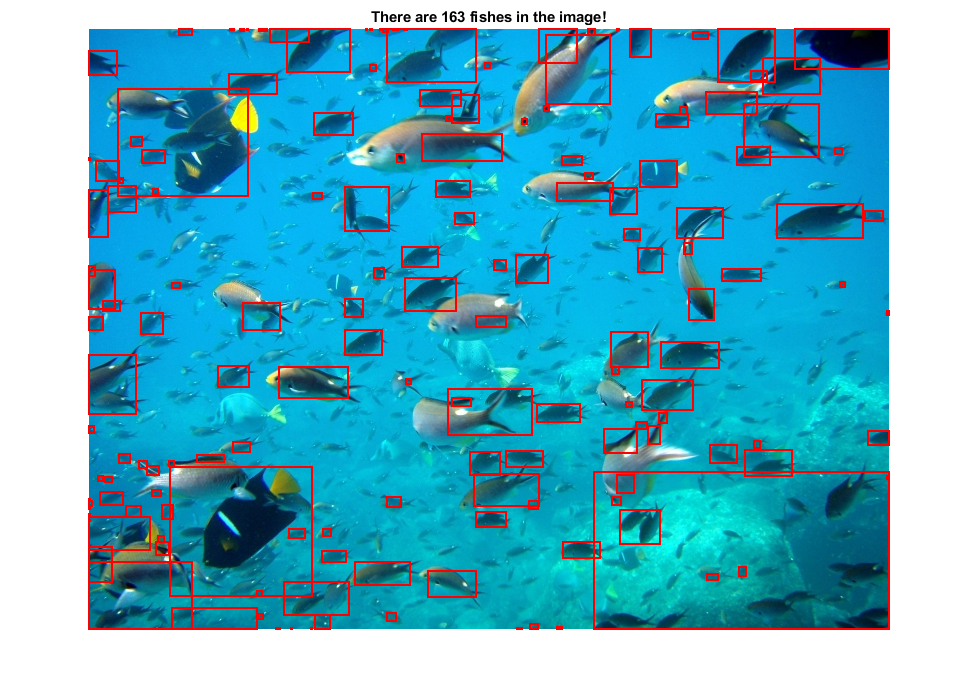

for x = 1:n
rectangle('Position',r(x).BoundingBox,"EdgeColor","r","LineWidth",1);
title(['There are ', num2str(n), ' fishes in the image!']); 
end